SVS Processing

(1) Set directories

clc; clear;
inum = 5; % SVS num
inDir = checkDir(['\Users\rishabhdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\SVS/z3697 svs' num2str(inum) '/']);
saveDir = checkDir(['/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/SVS/svs' num2str(inum) '/' ]);
if ~exist(saveDir,'dir')
    mkdir(saveDir)
end


**(2) Show raw image**

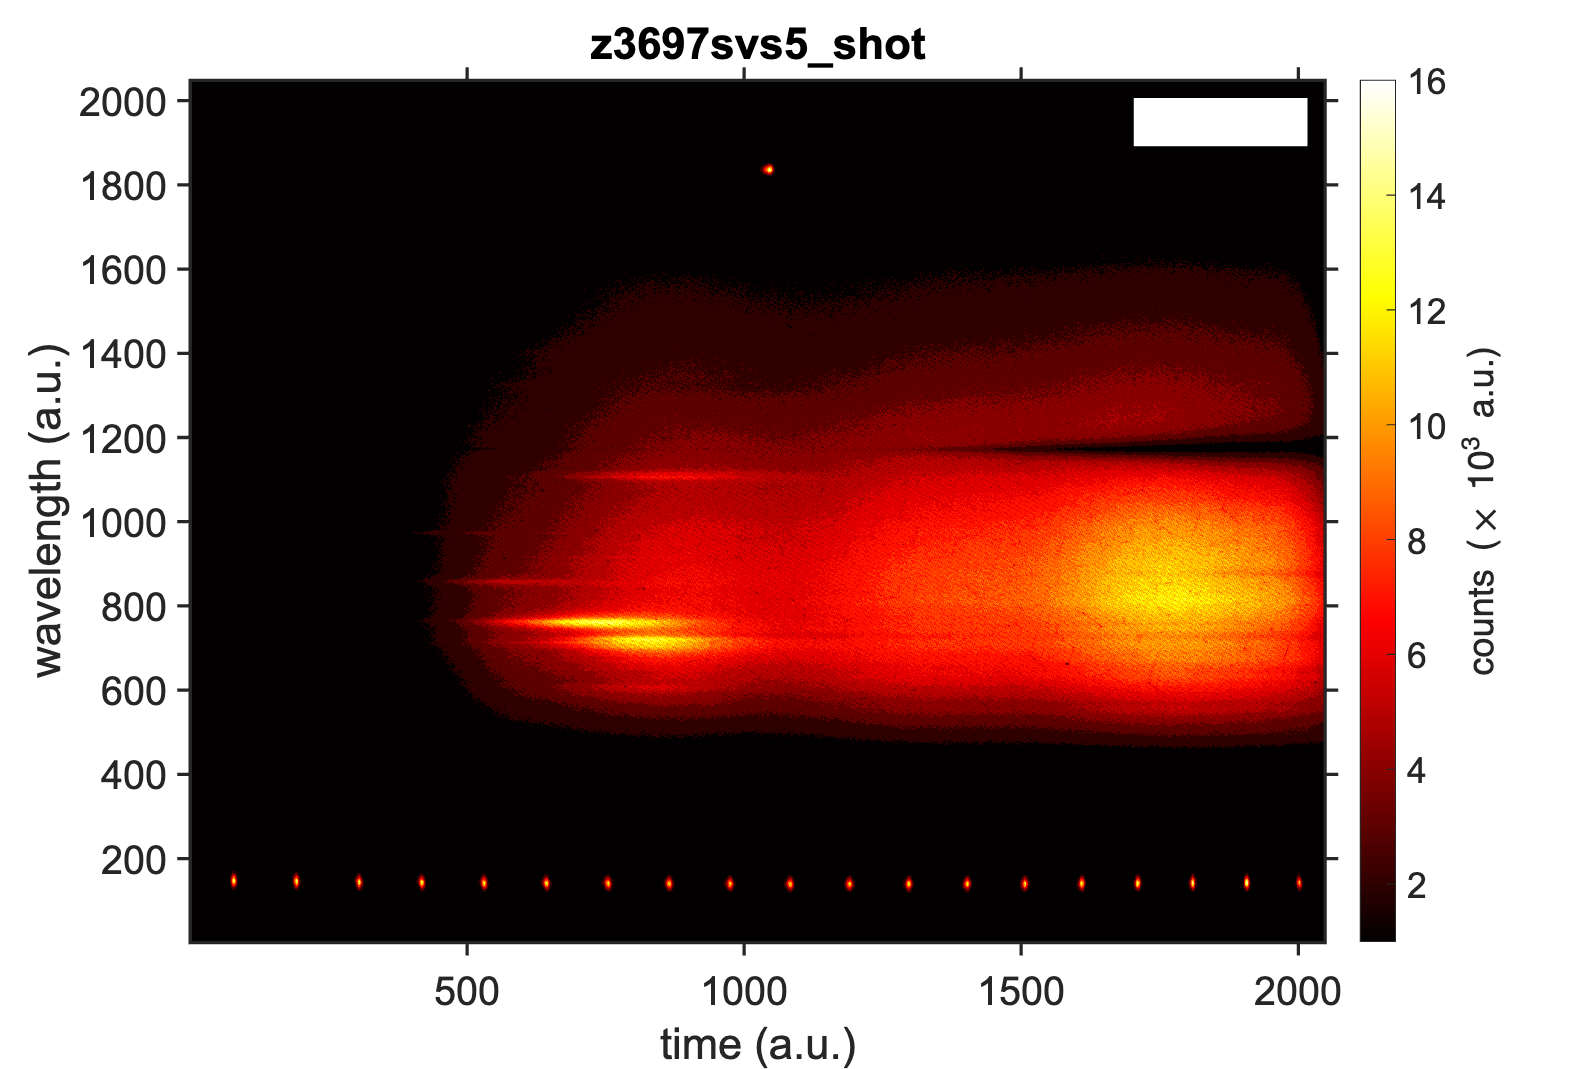

fid = 'z3697svs5_shot';
data = hdfread([inDir, fid, '.hdf'],'fore');

figure
imagesc(data/1e3);
set(gca,'Ydir','Normal');
colormap(hot)
title(strrep(fid,'_','\_'));

ylabel('wavelength (a.u.)');
xlabel('time (a.u.)');
set(gcf,'Position', [262   118   820   556]);
set(gca,'TickDir','out')
cb = colorbar(); ylabel(cb,'counts (\times 10^3 a.u.)')

formatPlots()

SVS5data.img = data; % store raw image in struct

exportgraphics(gcf,[saveDir, fid '_raw.tiff']);

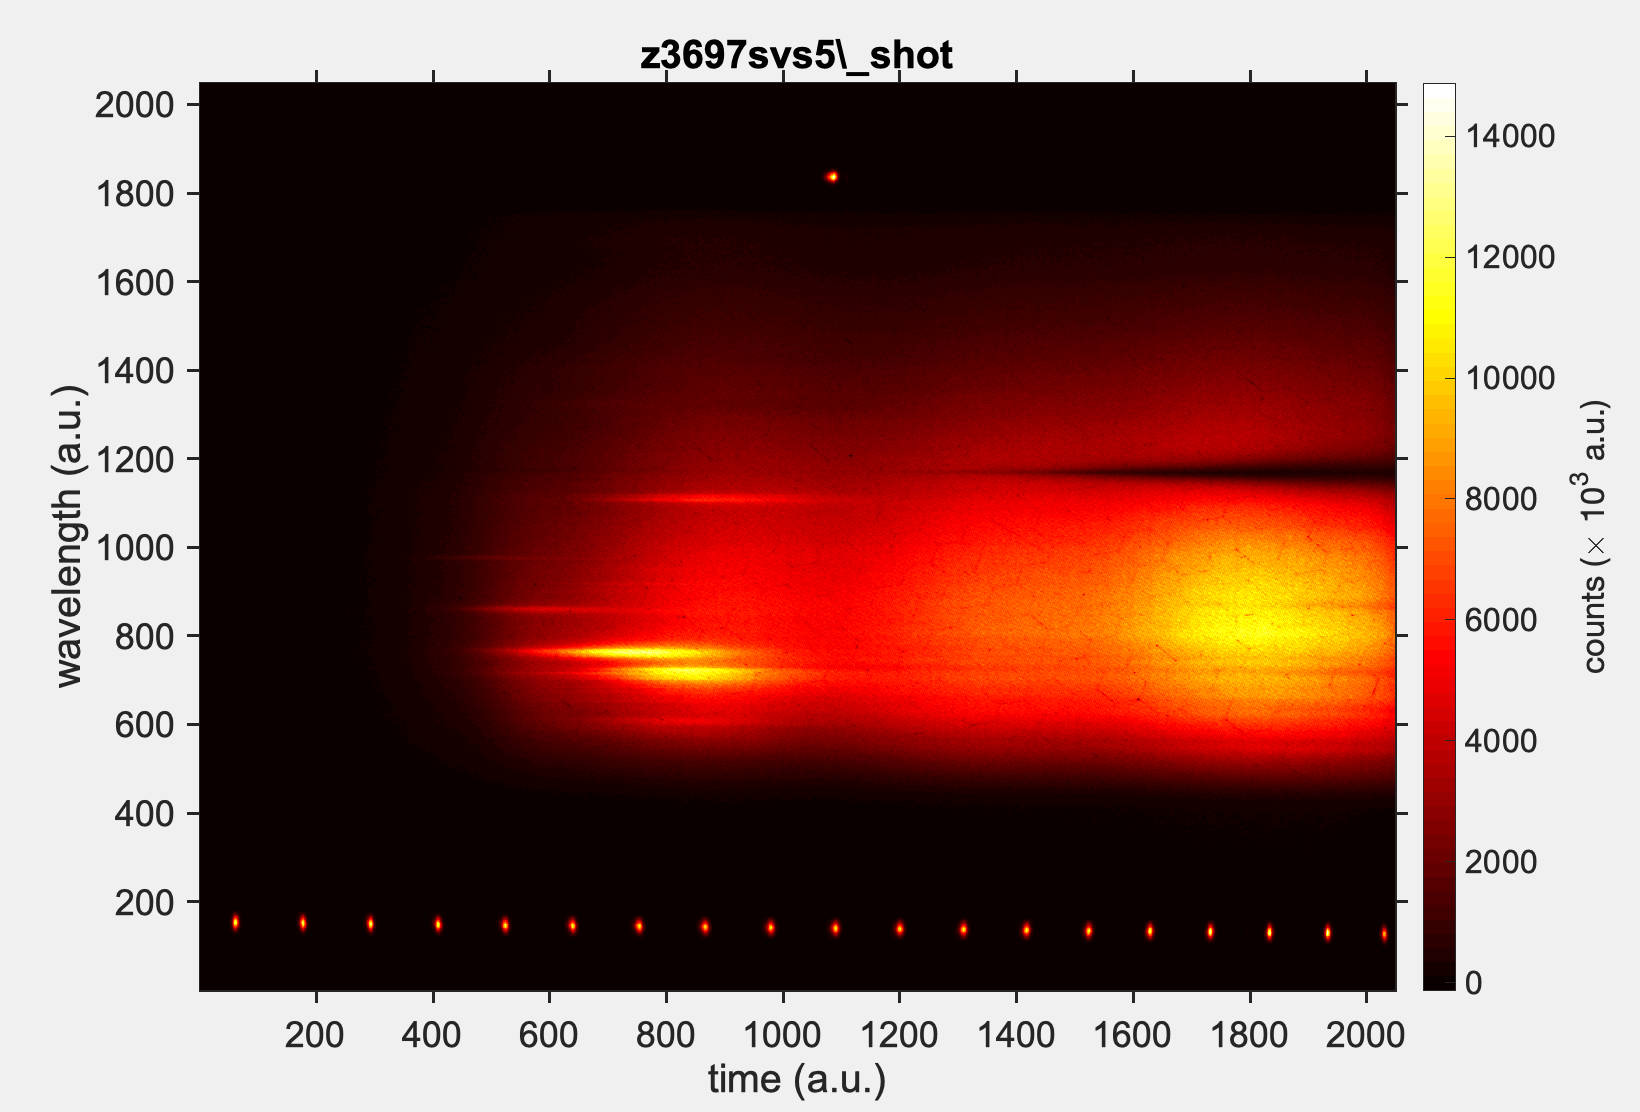

import SMASH.ImageAnalysis.Image
import SMASH.SpectroscopyAnalysis.SVSAnalysis.Spectroscopy
 
data=Image('z3697svs5_shot.hdf','sydor');
obj=Spectroscopy(data,5,'streak','Auto','False');
% apply distortion correction for the 500 ns sweepts
obj=obj.distortion('speed','500ns');
obj.distortionCal=obj.UnmodifiedData.Data;
view(obj.ActiveImage);
set(gca,'Ydir','Normal');
colormap(hot)
title(strrep(fid,'_','\_'));

ylabel('wavelength (a.u.)');
xlabel('time (a.u.)');
set(gcf,'Position', [262   118   820   556]);
set(gca,'TickDir','out')
cb = colorbar(); ylabel(cb,'counts (\times 10^3 a.u.)')

SVS5data.cor_img = obj.ActiveImage.Data;

formatPlots()

**(3) Alignment Testing and rectification**

Check if location of peaks become tilted in time

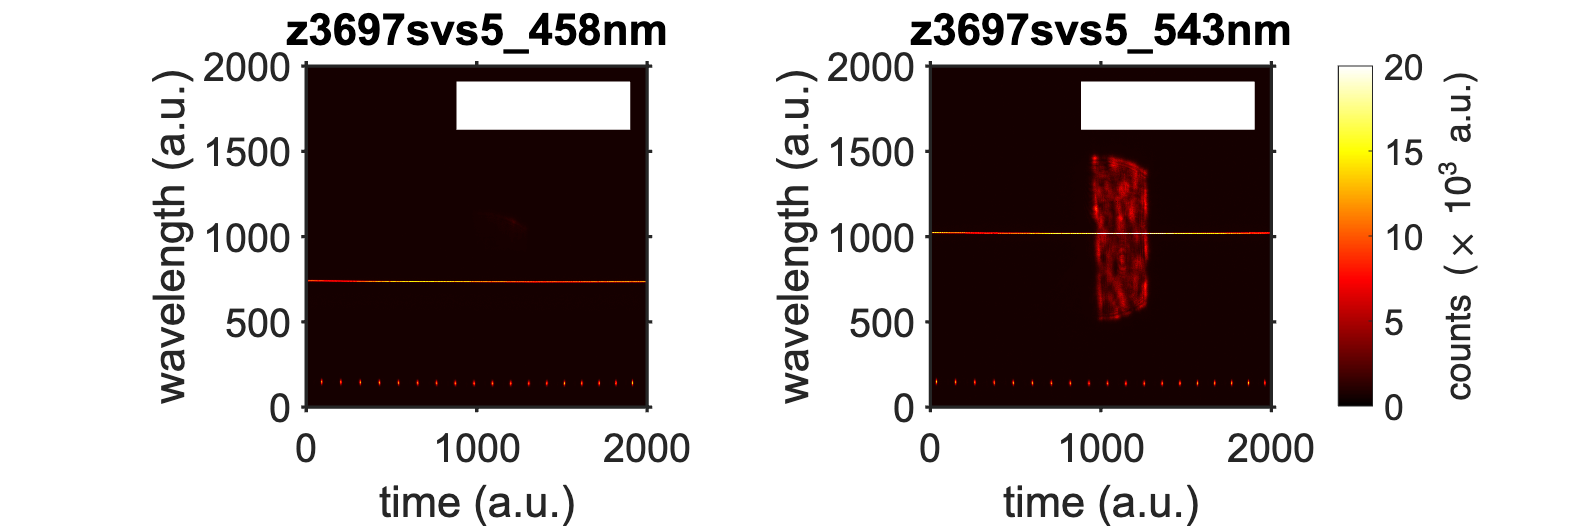

fid = {'z3697svs5_458nm', 'z3697svs5_543nm'}; % Calibration images
out = {};

figure
for ii = 1:length(fid)
    data = double(hdfread([inDir, fid{ii}, '.hdf'],'fore'));
    subplot(1,length(fid),ii) % plot
    imagesc(data/1e3);
    set(gca,'Ydir','Normal');
    colormap(hot)
    title(strrep(fid{ii},'_','\_'));
%     if ii == 1
        ylabel('wavelength (a.u.)');
%     else
%         yticklabels([]);
%     end
    xlabel('time (a.u.)');   
    if ii == length(fid)
    cb = colorbar(); ylabel(cb, 'counts (\times 10^3 a.u.)')
    end
    set(gca,'TickDir','out')
    xlim([0,2e3]); ylim([0,2e3]); axis square
    formatPlots();
    caxis([0,20]);
    out{ii} = data;
    
end
set(gcf,'Position', [0   0   1200   400]*1.5);
saveas(gcf,[saveDir, fid{ii} '_calibLines.png']);

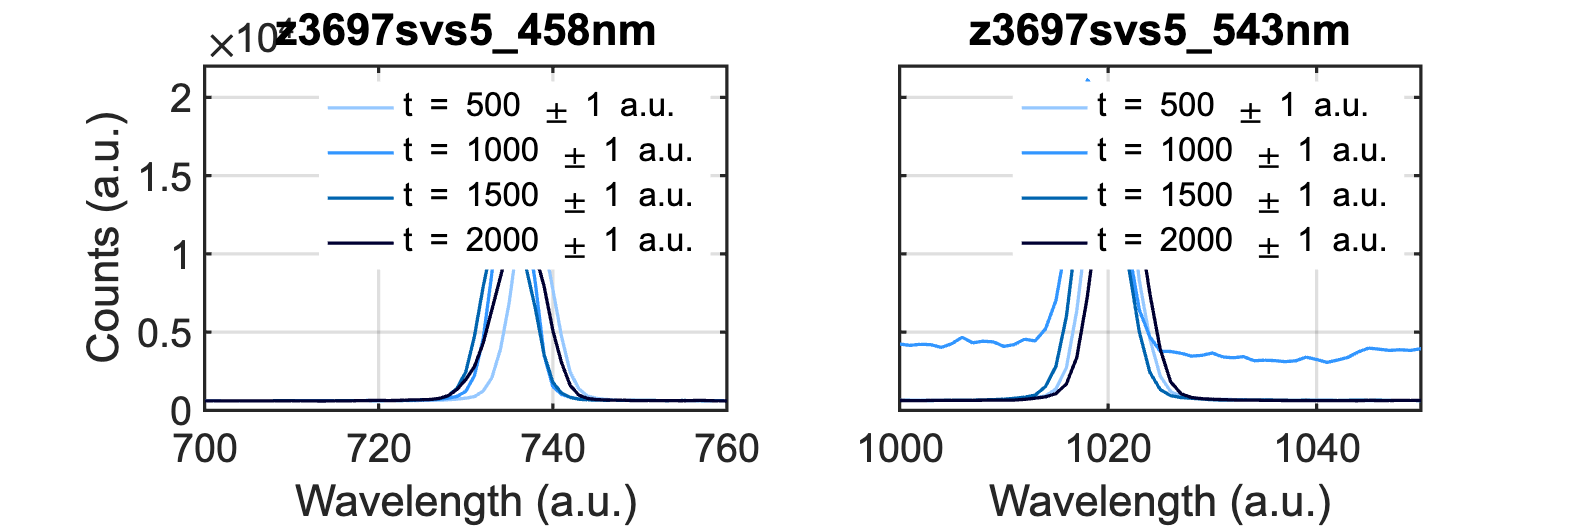

% Now plot lineouts at different times (a.u.)

tid = [500, 1000, 1500, 2000];

figure
for ii = 1:length(fid)
    subplot(1,length(fid),ii)
    data = out{ii};
    [nx,ny] = size(data); 
    for jj = 1:length(tid)
        Iq = 1/3 * (data(:,tid(jj)) + data(:,tid(jj)-1) + data(:,tid(jj)+1));
        plot(1:ny,Iq,'DisplayName',['t = ' num2str(tid(jj)) ' \pm 1 a.u.'],...
            'Linewidth',1.5,'Color',sqclr('b',jj*2-1)); hold on;
    end
    xlabel('Wavelength (a.u.)'); ylabel('Counts (a.u.)')
    grid on;
    title(strrep(fid{ii},'_','\_'));
    ylim([0,22e3]); 
    if ii == 1
        xlim([700,760]);
    else
        xlim([1000,1050]);
    end
    formatPlots()
end
subplot(1,2,2)
yticklabels([]); ylabel([])
set(gcf,'Position', [0   0   1200   400]*1.5);
saveas(gcf,[saveDir, fid{ii} '_alignment-1.png']);

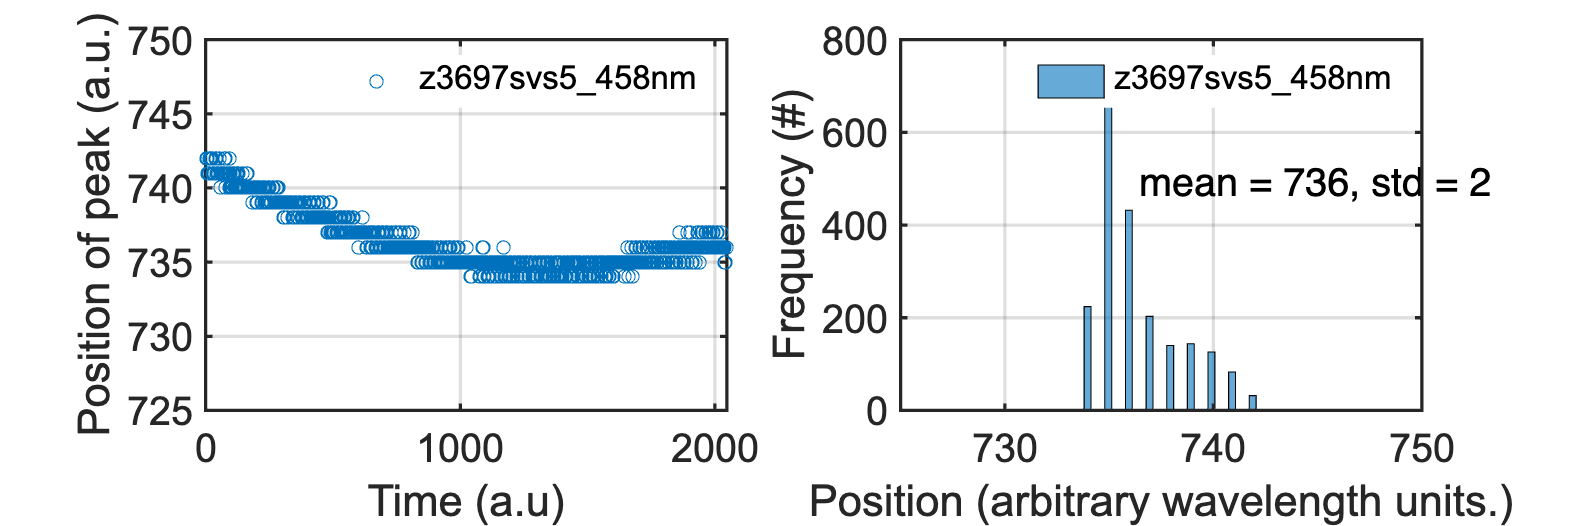

% Now find how peaks differ vs time

ii = 1;
data = out{ii};
pos = [];
[nx,ny] = size(data);
for jj = 2:ny-1
    Iq = 1/3 * (data(:,jj) + data(:,jj-1) + data(:,jj+1)); % Intensity lineout
    Iq(1:500) = 0; % clip to remove time markers
    [~,maxi] = max(Iq);
    pos = [pos; maxi];
end

y1 = mean(pos);

 figure
subplot(1,2,1)
plot(2:ny-1,pos,'o','DisplayName',strrep(fid{ii},'_','\_'));
xlabel('Time (a.u)'); ylabel('Position of peak (a.u.)');
grid on; ylim([725 750]);
formatPlots();
subplot(1,2,2) % histogram
histogram(pos,25,'DisplayName',strrep(fid{ii},'_','\_'))
text(mean(pos),500,['mean = ' num2str(mean(pos),3), ', std = ' num2str(std(pos),2)],'FontSize',18);
xlabel('Position (arbitrary wavelength units.)'); ylabel('Frequency (#)');
grid on; xlim([725,750]);
formatPlots();
set(gcf,'Position', [0   0   1200   400]*1.5);
saveas(gcf,[saveDir, fid{ii} '_alignment-2.png']);

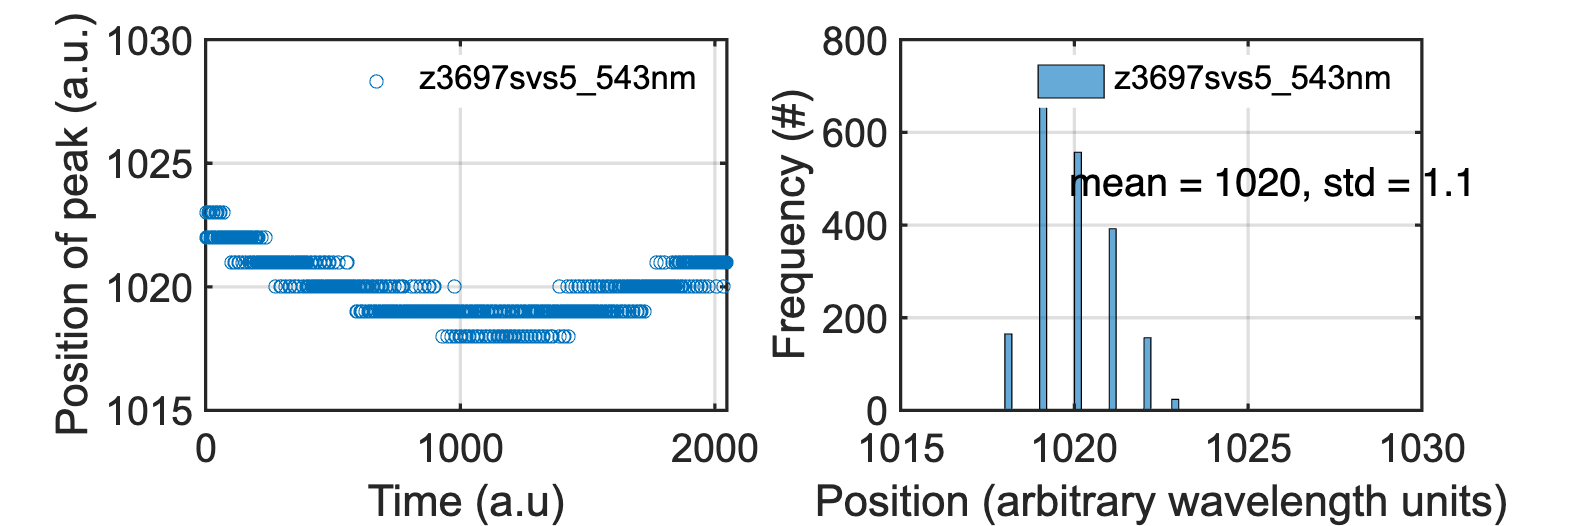


ii = 2;
data = out{ii};
pos = [];
[nx,ny] = size(data);
for jj = 2:ny-1
    Iq = 1/3 * (data(:,jj) + data(:,jj-1) + data(:,jj+1)); % Intensity lineout
    Iq(1:500) = 0; % clip to remove time markers
    [~,maxi] = max(Iq);
    pos = [pos; maxi];
end

figure
subplot(1,2,1)
plot(2:ny-1,pos,'o','DisplayName',strrep(fid{ii},'_','\_'));
xlabel('Time (a.u)'); ylabel('Position of peak (a.u.)');
grid on; 
 ylim([1015 1030]);
formatPlots();
subplot(1,2,2) % histogram
histogram(pos,25,'DisplayName',strrep(fid{ii},'_','\_'))
text(mean(pos),500,['mean = ' num2str(mean(pos),4), ', std = ' num2str(std(pos),2)],'FontSize',18);
xlabel('Position (arbitrary wavelength units)'); ylabel('Frequency (#)');
grid on; 
xlim([1015 1030]);
formatPlots();
set(gcf,'Position', [0   0   1200   400]*1.5);
saveas(gcf,[saveDir, fid{ii} '_alignment-3.png']);

y2 = mean(pos);

save([saveDir,'alignment.mat'],"y1","y2","nx","ny")

**(3) Wavelength calibration**

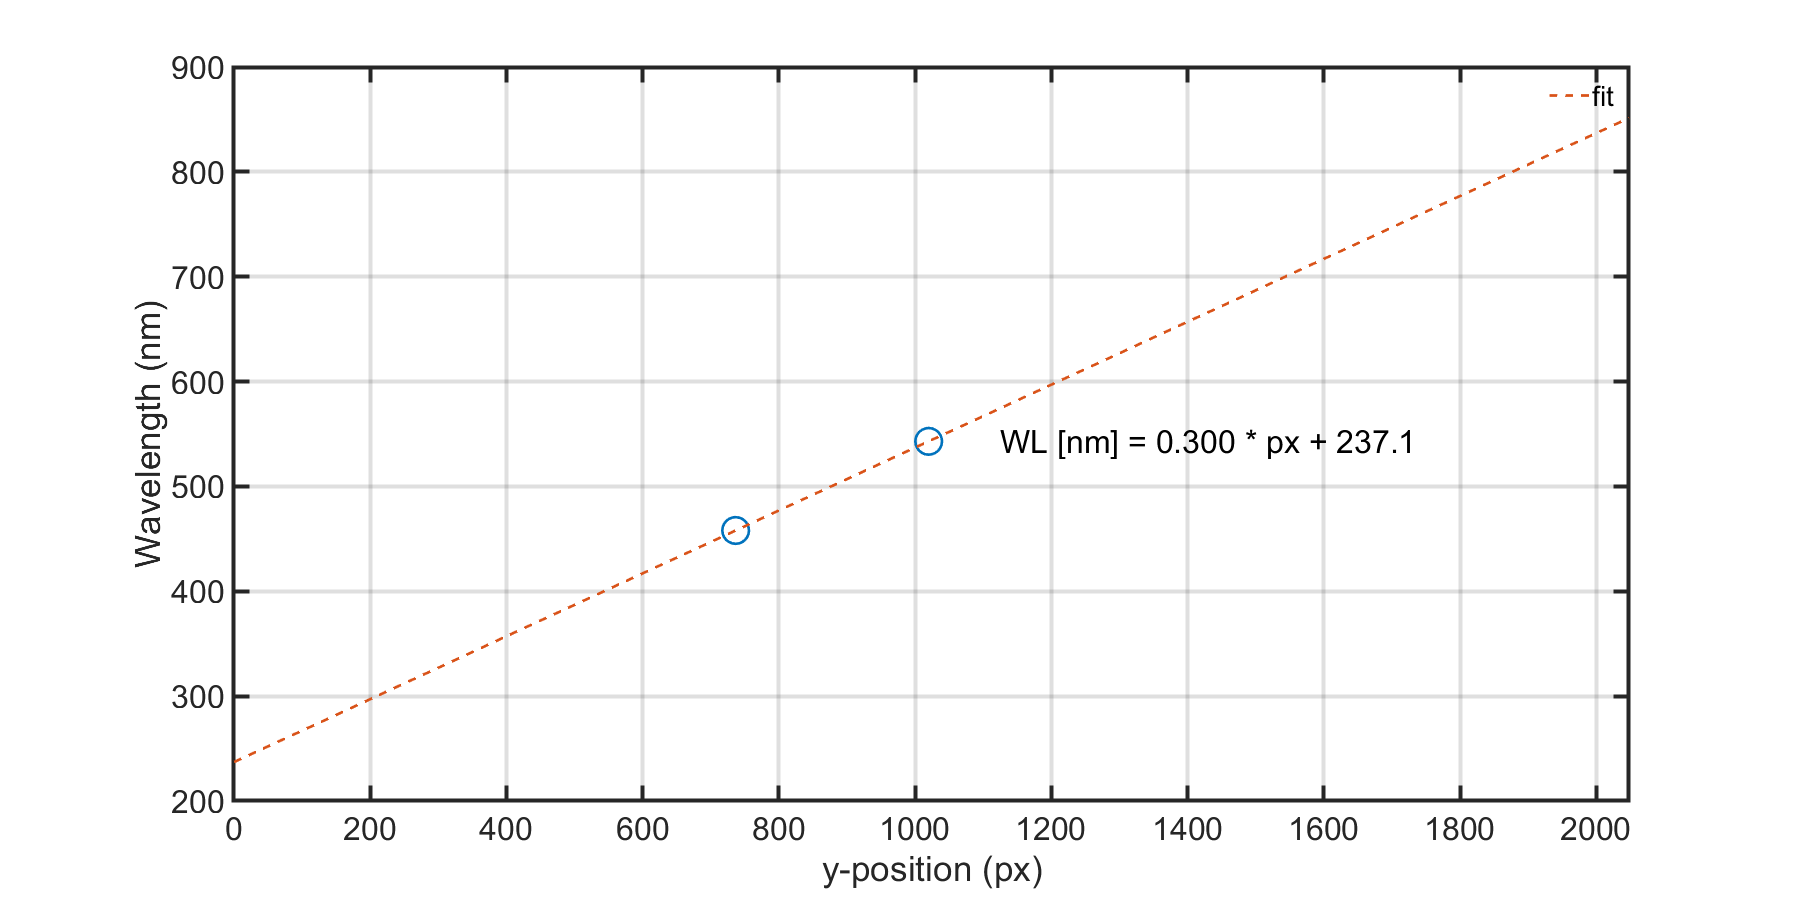

load([saveDir,'alignment.mat'],"y1","y2","nx","ny")
wl = [458, 543]; % actual wavelength, [nm]
P = polyfit([y1,y2],wl,1); % Px to wl [nm]
figure
plot([y1,y2],wl,'o',"markerSize",20,'LineWidth',2,'HandleVisibility','off'); hold on;
str = sprintf('WL [nm] = %0.3f * px + %0.1f',P(1),P(2));
xx = linspace(0,ny,100); yy = polyval(P,xx);
plot(xx,yy,'--','LineWidth',2,'DisplayName','fit');
text(mean(xx)+100,mean(yy), str,'FontSize',24);
ylabel('Wavelength (nm)'); xlabel('y-position (px)')
grid on; formatPlots();
xlim([0,ny])
set(gcf,'Position', [0   0   1200   600]*1.5);
saveas(gcf,[saveDir, 'wavelngth_calib.png']);

px2wl = @(x) P(1) * x + P(2)

px2wl = function_handle with value:
    @(x)P(1)*x+P(2)


wl2px = @(wl) (wl - P(2)) / P(1)

wl2px = function_handle with value:
    @(wl)(wl-P(2))/P(1)


% Save
save([saveDir 'svs5_wl.mat'],"px2wl","wl2px")
SVS5data.wl_cal.wl2px = wl2px;
SVS5data.wl_cal.px2wl = px2wl;

Only 2 points. Now add HgNe lamp and compare with known Hg and Ne spectra. 

*HgNe spectra not used for calibration. CCD is typically linearin wavelngth space. RiD 9/8/2022*

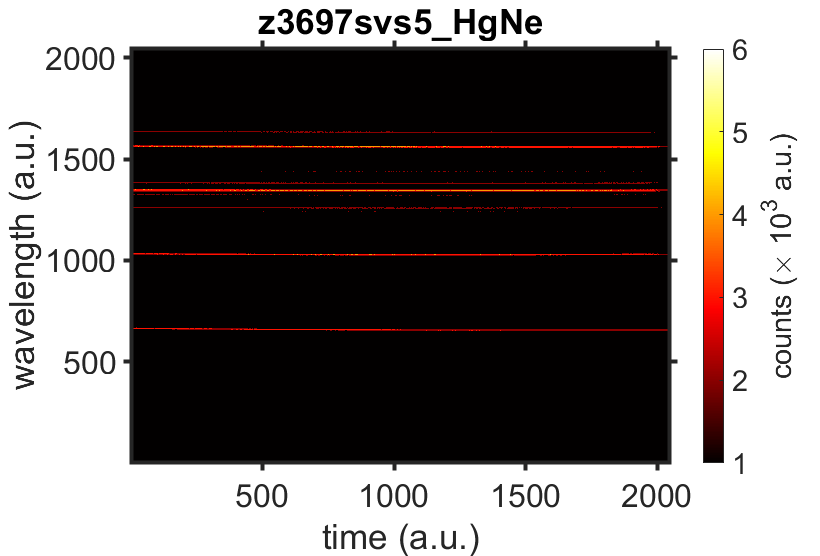

fid = 'z3697svs5_HgNe';
data = hdfread([inDir, fid, '.hdf'],'fore');

figure
imagesc(data/1e3);
set(gca,'Ydir','Normal');
colormap(hot)
title(strrep(fid,'_','\_'));

ylabel('wavelength (a.u.)');
xlabel('time (a.u.)');
set(gcf,'Position', [262   118   820   556]);
set(gca,'TickDir','out')
cb = colorbar(); ylabel(cb,'counts (\times 10^3 a.u.)')

formatPlots()

exportgraphics(gcf,[saveDir, fid '_raw.tiff']);

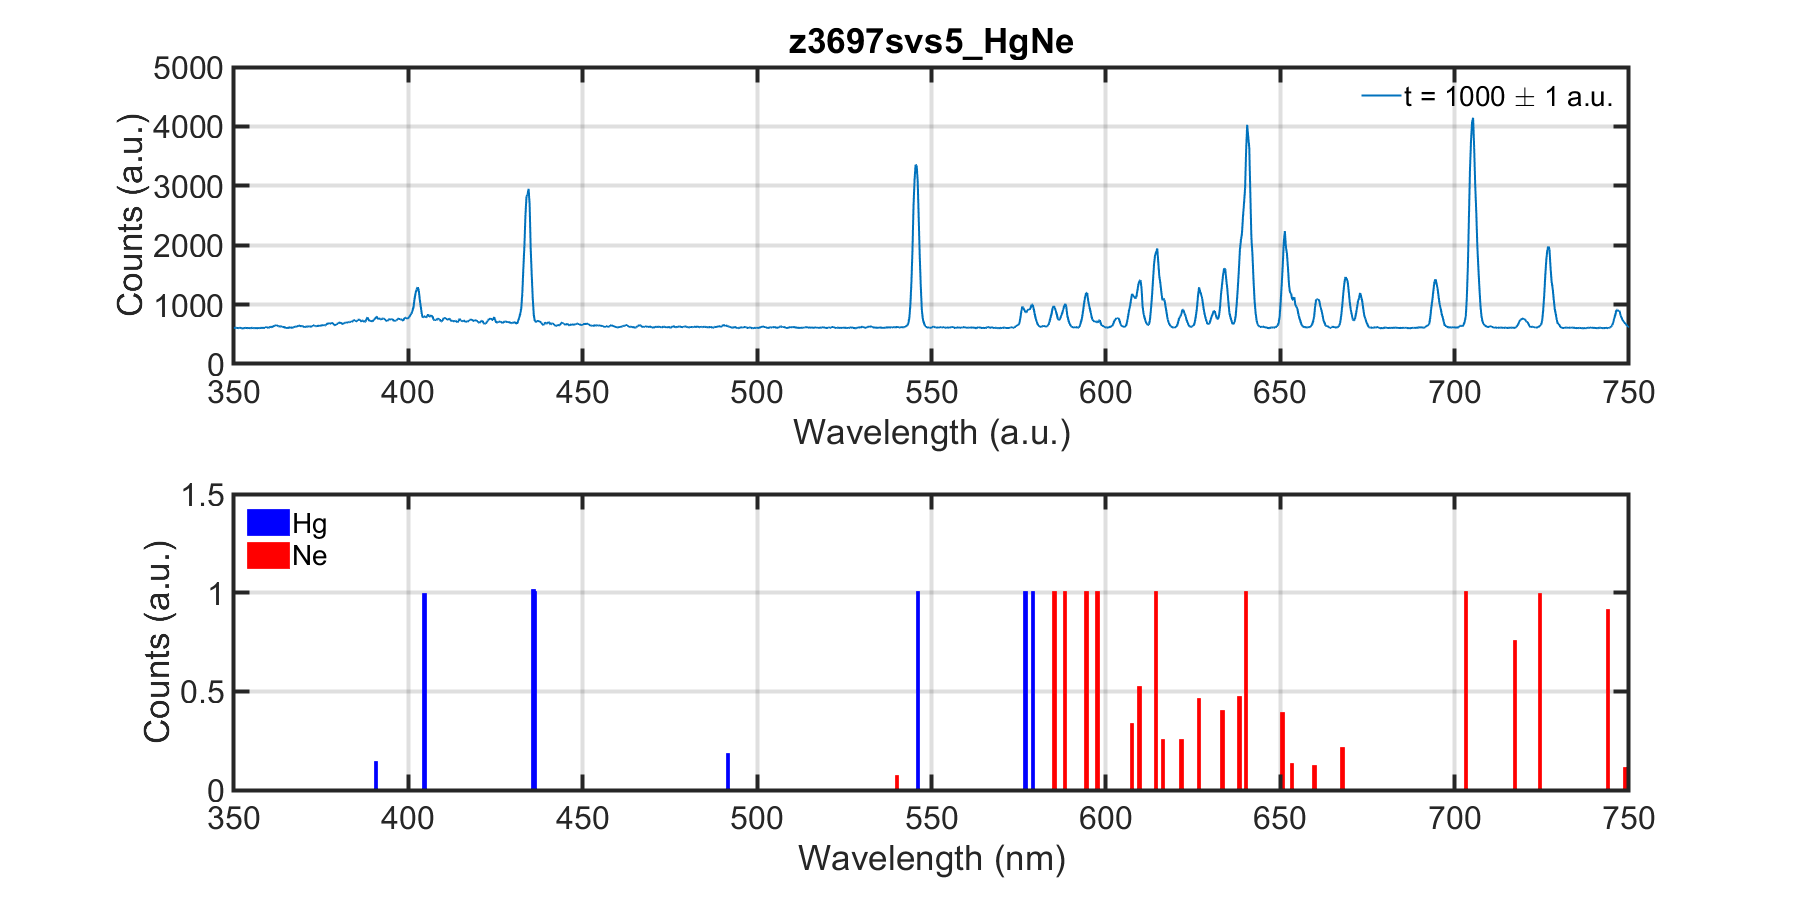


% Lineouts

tid = 1000;
[nx,ny] = size(data);
Iq = 1/3 * (data(:,tid) + data(:,tid-1) + data(:,tid+1));
figure
subplot(2,1,1)
plot(px2wl(1:ny),Iq,'DisplayName',['t = ' num2str(tid) ' \pm 1 a.u.'],...
            'Linewidth',1.5); hold on;
xlabel('Wavelength (a.u.)'); ylabel('Counts (a.u.)')
grid on;
title(strrep(fid,'_','\_'));
formatPlots(); xlim([350,750]); ylim([0,5e3]);


HgNeOriel6034 = importlines("C:\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\SVS\svs5\HgNeOriel6034.txt");
wl_HgNe = str2double(HgNeOriel6034(:,2)); I_HgNe = str2double(HgNeOriel6034(:,3)); 
idx_Hg = strcmpi(HgNeOriel6034(:,1),'Hg'); idx_Ne = strcmpi(HgNeOriel6034(:,1),'Ne'); 

subplot(2,1,2)
bar(wl_HgNe(idx_Hg),I_HgNe(idx_Hg),1,'FaceColor','b','EdgeColor','b',...
    'DisplayName','Hg','linewidth',2); hold on;

bar(wl_HgNe(idx_Ne),I_HgNe(idx_Ne),0.2,'FaceColor','r','EdgeColor','r',...
    'DisplayName','Ne','linewidth',2); hold on;

xlabel('Wavelength (nm)'); ylabel('Counts (a.u.)')
grid on;
formatPlots(); xlim([350,750]); ylim([0,1.5]);

set(gcf,'Position', [0   0   1200   300*2]*1.5);
legend('location','northwest');
saveas(gcf,[saveDir, 'HgNelines.png'])

**(4) Time Calibration.**

Need to know starting time marker and inter-marker separation


fid = 'z3697svs5_shot';
data = hdfread([inDir, fid, '.hdf'],'fore');
data = double(data);

% Show peaks correcpondingto comb markers
temp = data(140,:);
[m,n] = size(temp);
[pks,idx] = findpeaks(temp,'MinPeakDistance',50,'MinPeakHeight',1e3);
figure
subplot(2,2,1);
plot(1:n,temp,'linewidth',1.5); hold on;
plot(idx,pks,'om','markersize',15); 
 xlim([0,n]); grid on;
ylabel('counts (a.u.)');
formatPlots(); title('Comb');
xticks(0:500:2000);xticklabels([]);
legend('off');

% Show machine time marker

temp = data(1700:1900,:);
temp = sum(temp,1);
[m,n] = size(temp);
[mkr,mkr_idx] = findpeaks(temp,'MinPeakDistance',50,'MinPeakHeight',3e5);
subplot(2,2,2);
plot(1:n,temp,'linewidth',1.5); hold on;
plot(mkr_idx,mkr,'om','markersize',15); 
 xlim([0,n]); grid on;
ylabel('counts (a.u.)');
formatPlots(); title('Machine time marker');
xticks(0:500:2000);xticklabels([]);
legend('off');


subplot(2,2,3);
delt = 28.6; % [ns] comp spacing
machine_time = 3100; % [ns], corresponds to mkr_idx
t1 = 0; tend = t1 + (numel(pks)-1) * delt;
t = linspace(t1,tend,numel(pks));
plot(idx,t,'o','markersize',15); hold on;
P = polyfit(idx,t,1); % px to time [ns]
xx = linspace(0,n,100); % px
yy = polyval(P,xx); % ns
plot(xx,yy,'-','color','r','linewidth',1.5); 
xlabel('x (px)');
xticks(0:500:2000);
ylabel({'time from', 'first marker (ns)'});
legend('off');
str = sprintf('t = %0.2f * px + %0.2f',P(1),P(2))
text(mean(xx)-500,mean(yy),str,'FontSize',24)
grid on; formatPlots();
xlim([0,n])
legend('off');


m = P(1)
c = machine_time - m * mkr_idx; 

px2t = @(x) m * x + c; % px to ns
t2px = @(t) (t - c) / m; % ns to px

subplot(2,2,4);
px = 1:n; t = px2t(px);
plot(px,t,'-','color','b','linewidth',1.5); hold on;
plot(mkr_idx,machine_time,'ro','Markersize',15);
xlabel('x (px)');
ylabel('t (ns)');
legend('off');
str = sprintf('t = %0.2f * px + %0.2f',m,c)
text(mean(px)-500,mean(t),str,'FontSize',24)
grid on; formatPlots();
xlim([0,n]); xticks(0:500:2000);
set(gcf,'Position', [0   0   1200   1600]*1.5);
legend('off');

saveas(gcf,[saveDir, 'timeCalibration.png'])

% Save
save([saveDir 'svs5_time_calib.mat'],"px2t","t2px")
SVS5data.t_cal.px2t = px2t;
SVS5data.t_cal.t2px = t2px;

save([saveDir 'svs5data.mat'],"SVS5data")



(5) Instrument boradening

Use the blue and green laser lines

fid = {'z3697svs5_458nm', 'z3697svs5_543nm'}; % Calibration images
img = {};

load([saveDir 'svs5data.mat']);

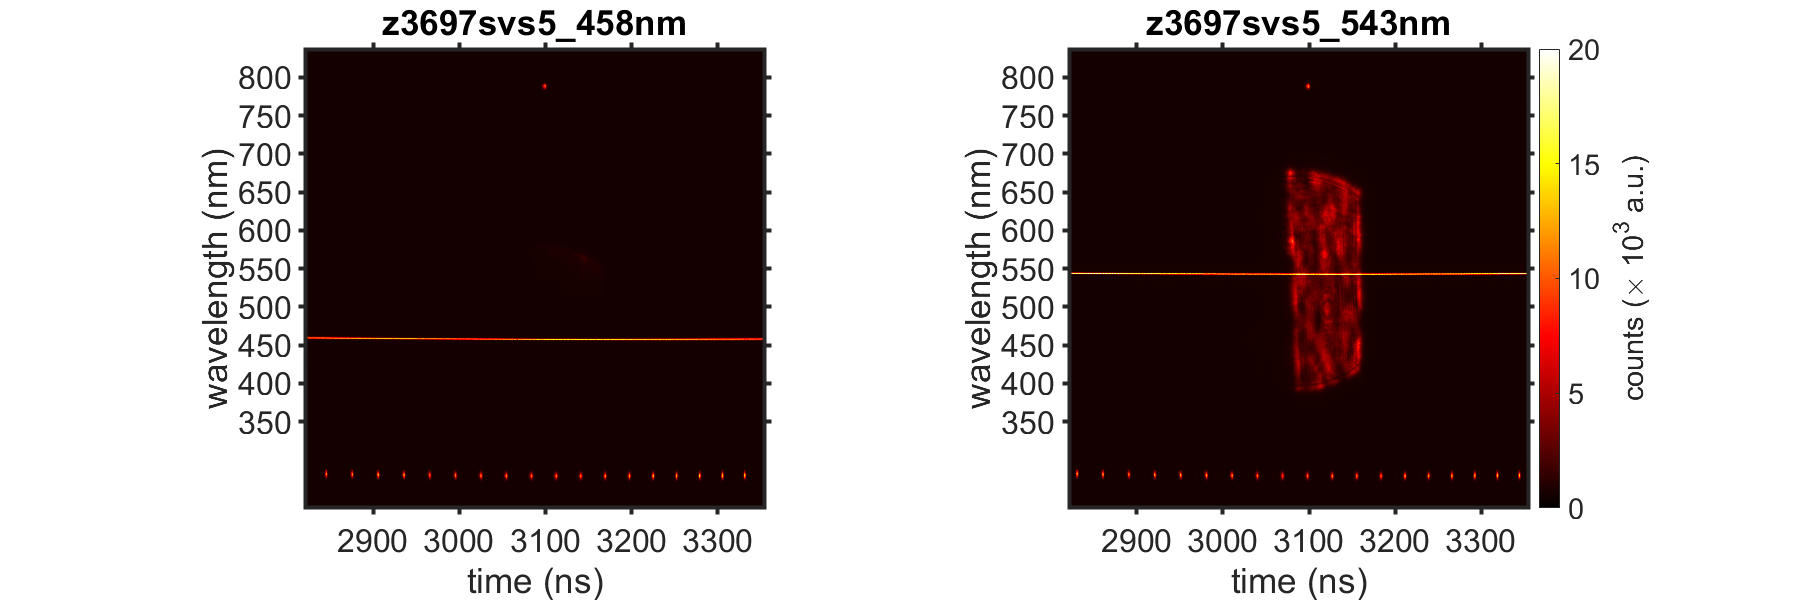

wl2px = SVS5data.wl_cal.wl2px; px2wl = SVS5data.wl_cal.px2wl;
t2px = SVS5data.t_cal.t2px; px2t = SVS5data.t_cal.px2t;

xlabels = 2800:100:3400; % ns
ylabels = 350:50:800; % nm

figure
for ii = 1:length(fid)
    data = double(hdfread([inDir, fid{ii}, '.hdf'],'fore'));
    subplot(1,length(fid),ii) % plot
    imagesc(data/1e3);
    set(gca,'Ydir','Normal');
    colormap(hot)
    title(strrep(fid{ii},'_','\_'));
    xticks(t2px(xlabels'));
    xticklabels(xlabels');
    yticks(wl2px(ylabels'));
    yticklabels(ylabels');

    ylabel('wavelength (nm)');
    xlabel('time (ns)');   
    if ii == length(fid)
    cb = colorbar(); ylabel(cb, 'counts (\times 10^3 a.u.)')
    end
    set(gca,'TickDir','out')
    xlim([0,2e3]); ylim([0,2e3]); axis square
    formatPlots();
    caxis([0,20]);
    img{ii} = data;
    
end
set(gcf,'Position', [0   0   1200   400]*1.5);
saveas(gcf,[saveDir, fid{ii} '_calibLines.png']);

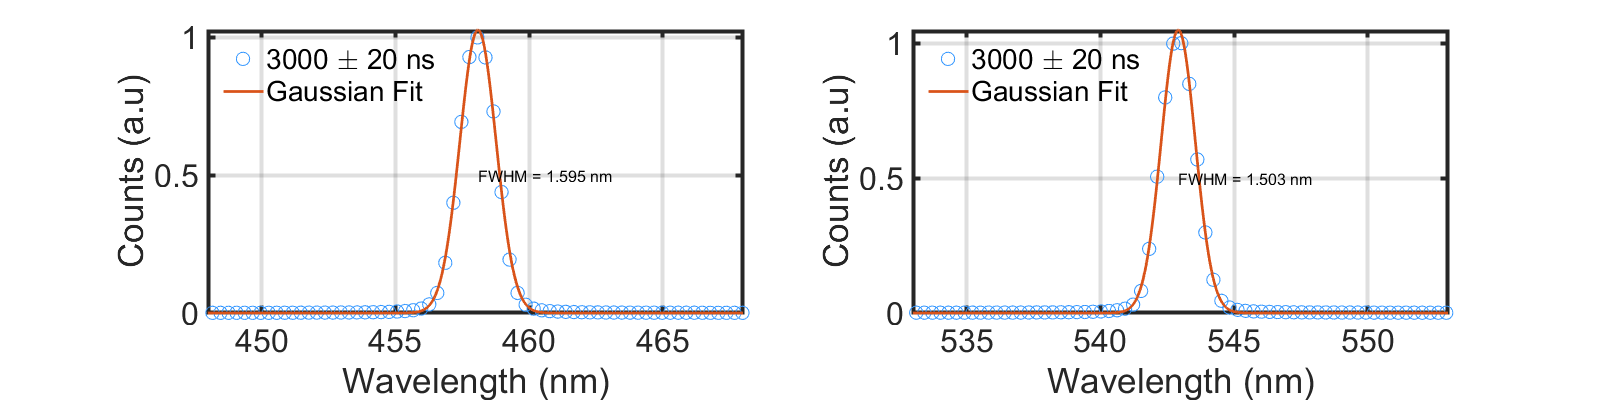



% Lineouts
tid = 3000;
figure(); 
sigma = [0, 0];
for jj = 1:numel(img)
    data = img{jj};
    [m,n] = size(data);
    t = 1:m; wl = 1:n; % px
    t = px2t(t); wl = px2wl(wl); % convert
    [tt,wl] = meshgrid(t,wl); 
    

    Lq = linspace(350,800,round(wl2px(800)-wl2px(350))); 
    tq = tid.* ones(size(Lq)); N = 20 * round((t2px(3000)-t2px(2999)));  tstp = 1/(N/20);
    
        out{jj} =  getavgLineout(tt,wl,data,tq,Lq,tstp,N);
        out{jj} = out{jj} - mean(out{jj}(1:10)); % zero the signal
        
        % get gaussian fit
        [sigma(jj),mu,A]=mygaussfit(Lq,out{jj}/max(out{jj}));
        xx = linspace(min(Lq),max(Lq),20 * numel(Lq));
      
        subplot(1,2,jj)
        plot(Lq,out{jj}/max(out{jj}),'o','markersize',10,'DisplayName',[num2str((tid),4) ' \pm ' num2str(N*tstp) ' ns'],'Color',sqclr('b',ii*2-1)); hold on;
        plot(xx,gaussianFn(xx,mu,sigma(jj),A),'Linewidth',2,'Color','#D95319','DisplayName','Gaussian Fit');
        text(mu,0.5,['FWHM = ' num2str(2.355 * sigma(jj),4) ' nm'],'Fontsize',12);
       
end
subplot(1,2,1); xlim(458+ [-10,10]); grid on; formatPlots(); ylabel('Counts (a.u)'); legend('location','northwest'); xlabel('Wavelength (nm)')
subplot(1,2,2); xlim(543+ [-10,10]); grid on; formatPlots(); ylabel('Counts (a.u)'); xlabel('Wavelength (nm)')
legend('location','northwest');
set(gcf,'Position',[0 0 1600 400]);

fwhm = 2 * sqrt(2 * log(2)) .* sigma;

SVS5data.broadening = fwhm;
save([saveDir 'svs5data.mat'],"SVS5data")

(6) Correct for instrument response & filter - LDLS

Here wecalculatethe system response function

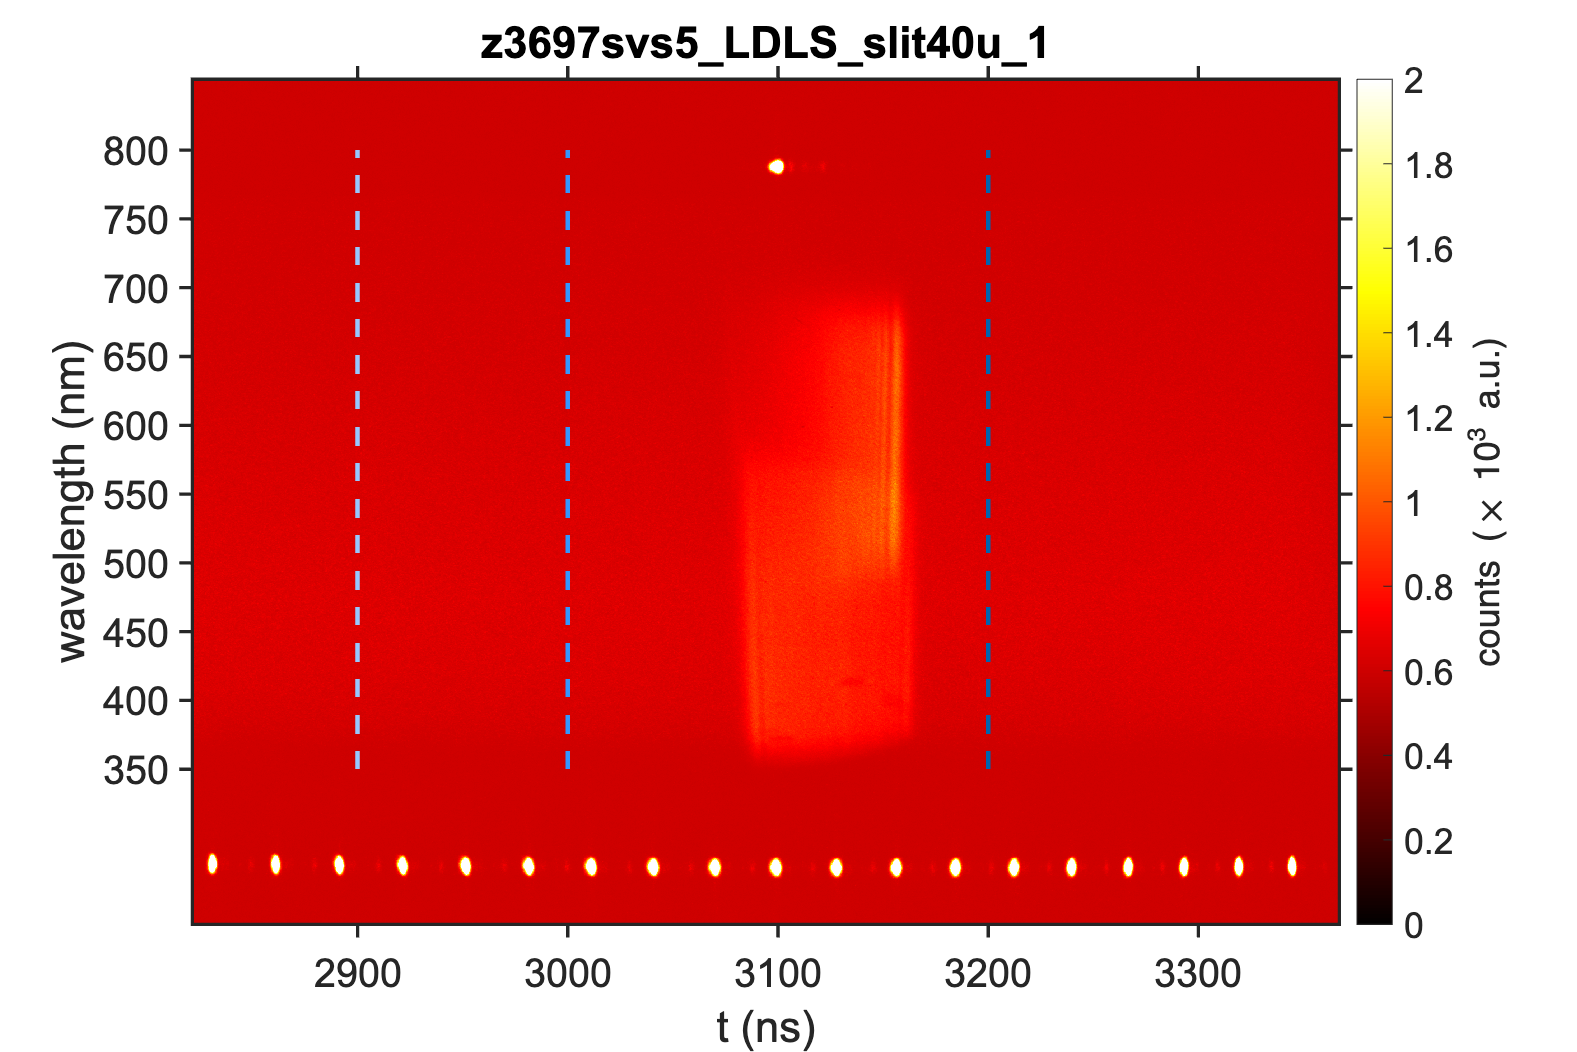

fid = 'z3697svs5_LDLS_slit40u_1';
data = hdfread([inDir, fid, '.hdf'],'fore');
data = double(data);

f1 = figure();
imagesc(data/1e3); set(gca,'Ydir','Normal');
colormap(hot); title(strrep(fid,'_','\_'));
xlabels = 2800:100:3400;

% calibration
load([saveDir 'svs5data.mat']); 
wl2px = SVS5data.wl_cal.wl2px; px2wl = SVS5data.wl_cal.px2wl; 
t2px = SVS5data.t_cal.t2px; px2t = SVS5data.t_cal.px2t; 
xticks(t2px(xlabels'));
xticklabels(xlabels');
xlabel('t (ns)');
ylabels = 350:50:800;
yticks(wl2px(ylabels'));
yticklabels(ylabels');
ylabel('wavelength (nm)');
set(gca,'TickDir','out')
cb = colorbar(); ylabel(cb,'counts (\times 10^3 a.u.)')
set(gcf,'Position', [0   0   1200  800]);
formatPlots()

% lineouts

tid = [2900, 3000, 3200];
figure(f1);
hold on;

for ii = 1:numel(tid)
plot(t2px([tid(ii),tid(ii)]),wl2px([350,800]),'--','Color',sqclr('b',ii*2-1),'Linewidth',2); hold on;
end

% Lineouts
[m,n] = size(data);
t = 1:m; wl = 1:n; % px
t = px2t(t); wl = px2wl(wl); % convert
[tt,wl] = meshgrid(t,wl); 

f2 =  figure();
Lq = linspace(350,800,round(wl2px(800)-wl2px(350))); 
tot = 0 * Lq;
for ii = 1:numel(tid)
    tq = tid(ii) .* ones(size(Lq)); 
    N = 20 * round((t2px(3000)-t2px(2999)));  tstp = 1/(N/20);
    out =  getavgLineout(tt,wl,data,tq,Lq,tstp,N);
    out = out - mean(out(1:10)); % zero teh signal
    figure(f2);
%     plot(Lq,out/5e3,'Linewidth',2,'DisplayName',[num2str(tid(ii)) ' ns'],'Color',sqclr('b',ii*2-1)); hold on; 
    plot(Lq,out/max(out),'Linewidth',2,'DisplayName',[num2str((tid(ii)),4) ' \pm ' num2str(N*tstp) ' ns'],'Color',sqclr('b',ii*2-1)); hold on;
    figure(f1);
    plot(tq,Lq,'--',...
        'HandleVisibility','off','Color',sqclr('b',ii*2-1));
    tot = tot + out/max(out);
end
figure(f2);
avg = smoothdata(tot/numel(tid),'movmean','SmoothingFactor',0.05);
plot(Lq,avg,'r','DisplayName','Mean','LineWidth',2);
set(gcf,'Position', [0   0   1200  400]);
xlabel('Wavelength (nm)'); ylabel('Counts (a.u.)')
xlim([400,750]); grid on; formatPlots();
exportgraphics(gcf,[saveDir, fid '-lineout.tiff']);
figure(f1);
legend('off');
caxis([0,2])
exportgraphics(gcf,[saveDir, fid '.tiff']);

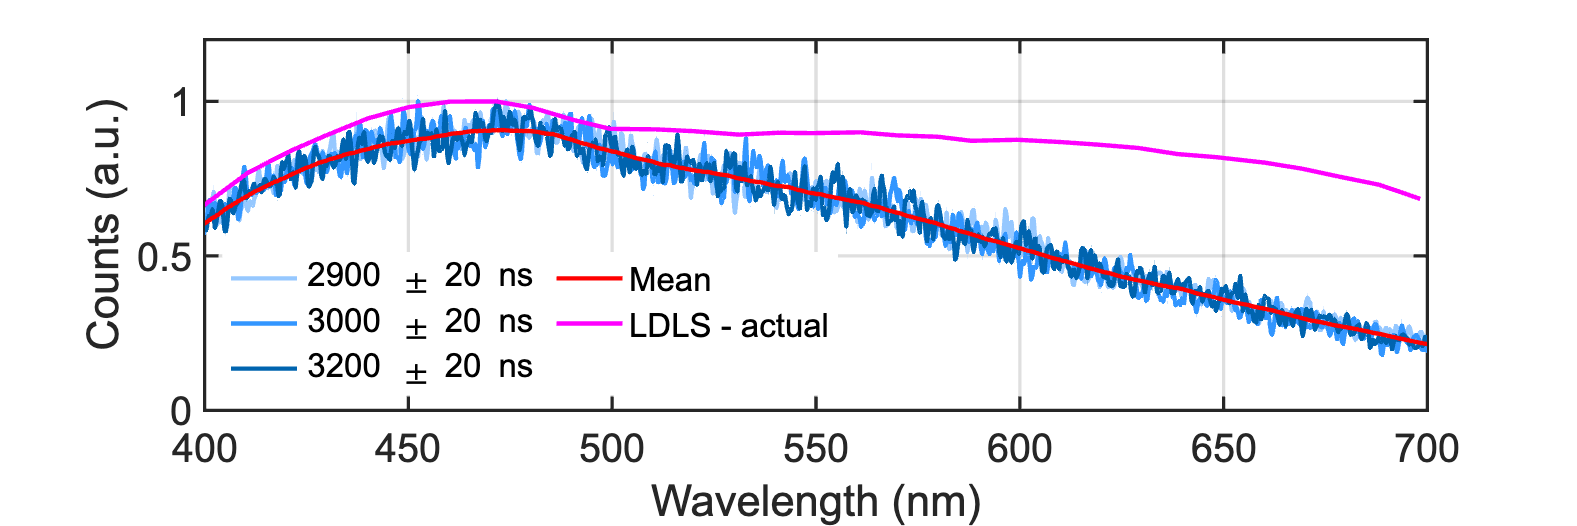

% Import measures LDLS spectrum 
ldls = importLDLS(checkDir("\Users\rdatta\Dropbox (MIT)\PUFFIN\Codes\MARZ\SVS\LDLS_shape_oct_2015.dat"), [7, Inf]);
ldls_wl = ldls.ColumnDefinitions / 10; % nm
ldls_I = ldls.VarName2; ldls_I = ldls_I / max(ldls_I); 

figure(f2);
plot(ldls_wl,ldls_I,'Color',[1,0,1],'LineWidth',2,'DisplayName','LDLS - actual');
legend('Location','southwest','NumColumns',2);
xlim([400,700]); ylim([0,1.2]);

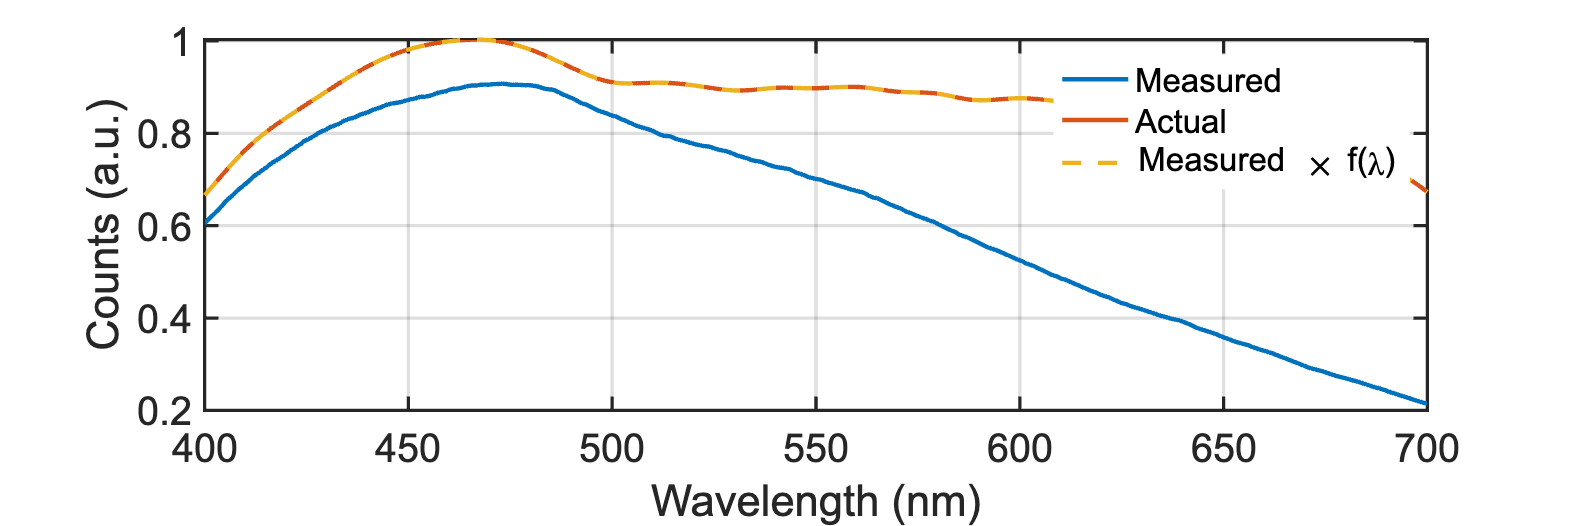

% perform spline fits to ldls spectra
wl = linspace(400,700,600);
meas = spline(Lq,avg,wl);
actual = spline(ldls_wl,ldls_I,wl);

f = actual ./ meas;

resp_fn = @(x) spline(wl,f,x);

SVS5data.sys_resp_fn = resp_fn;

figure
plot(wl,meas,'LineWidth',2,'DisplayName','Measured'); hold on;
plot(wl,actual,'LineWidth',2,'DisplayName','Actual');
plot(wl,meas .* resp_fn(wl),'--','LineWidth',2,'DisplayName','Measured \times f(\lambda)');
xlabel('Wavelength (nm)'); ylabel('Counts (a.u.)');
xlim([400,700]); grid on; formatPlots();
set(gcf,'Position', [0   0   1200  400]);

save([saveDir 'svs5data.mat'],"SVS5data");

(7) Show corrected spectra

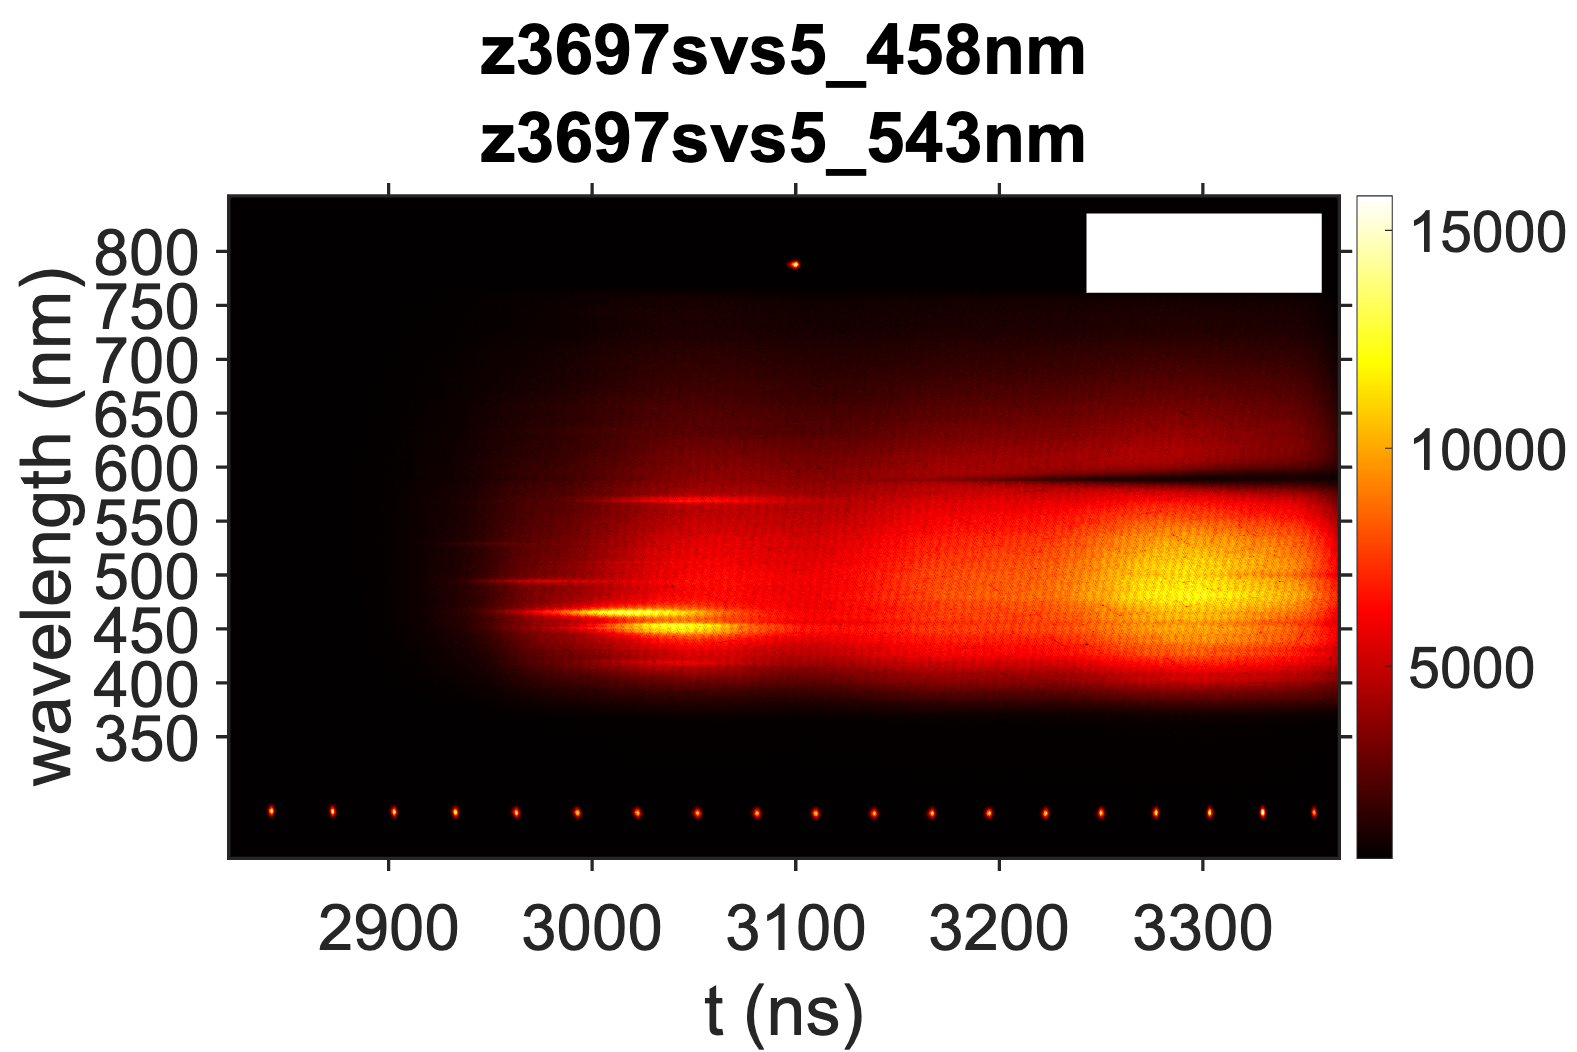

load([saveDir 'svs5data.mat']);

f1 = figure();
imagesc(SVS5data.img); set(gca,'Ydir','Normal');
colormap(hot); title(strrep(fid,'_','\_'));
xlabels = 2800:100:3400;

% calibration
xticks(SVS5data.t_cal.t2px(xlabels'));
xticklabels(xlabels');
xlabel('t (ns)');
ylabels = 350:50:800;
yticks(SVS5data.wl_cal.wl2px(ylabels'));
yticklabels(ylabels');
ylabel('wavelength (nm)');
set(gca,'TickDir','out')
cb = colorbar(); ylabel(cb,'counts (\times 10^3 a.u.)')

formatPlots(800)
set(gcf,'Position', [0   0   1200  800]);


% exportgraphics(gcf,[saveDir, fid '_calibrated.tiff']);

Error using exportgraphics
Additional, unrecognized inputs were specified.


% lineouts

tid = [3000,3050,3100];
figure(f1);
hold on;
for ii = 1:numel(tid)
    plot(SVS5data.t_cal.t2px([tid(ii),tid(ii)]),SVS5data.wl_cal.wl2px([350,700]),'--','Color',sqclr('b',ii*2-1),'Linewidth',2,"HandleVisibility",'off');

end

% Lineouts
[m,n] = size(data);
t = 1:m; wl = 1:n; % px
t = SVS5data.t_cal.px2t(t); wl = SVS5data.wl_cal.px2wl(wl); % convert
[tt,wl] = meshgrid(t,wl); 

f2 =  figure();
Lq = linspace(400,700,round(SVS5data.wl_cal.wl2px(700)-SVS5data.wl_cal.wl2px(400))); 
for ii = 1:numel(tid)
    tq = tid(ii) .* ones(size(Lq)); 
    N = round((SVS5data.t_cal.t2px(3000)-SVS5data.t_cal.t2px(2999)));  tstp = 1/N;
    out =  getavgLineout(tt,wl,data,tq,Lq,tstp,N);
    
     figure(f2); 
     subplot(2,1,1)
    plot(Lq,out,'Linewidth',2,'DisplayName',[num2str(tid(ii)) ' \pm ' num2str(N*tstp) ' ns'],'Color',sqclr('b',ii*2-1)); hold on; 
%     plot(Lq,out,'Linewidth',2,'DisplayName',[num2str(tid(ii)) ' \pm ' num2str(N*tstp) ' ns'],'Color','k'); hold on;
    
    subplot(2,1,2) % Plot corrected spectra
    plot(Lq,out.*SVS5data.sys_resp_fn(Lq),'Linewidth',2,'DisplayName',[num2str(tid(ii)) ' \pm ' num2str(N*tstp) ' ns'],'Color',sqclr('b',ii*2-1)); hold on; 
%     plot(Lq,out.*SVS5data.sys_resp_fn(Lq),'Linewidth',2,'DisplayName',[num2str(tid(ii)) ' \pm ' num2str(N*tstp) ' ns'],'Color','k'); hold on;
    figure(f1);
    plot(tq,Lq,'--',...
        'HandleVisibility','off','Color',sqclr('b',ii*2-1))
end
figure(f1);
exportgraphics(gcf,[saveDir, fid '_calibrated_1.tiff']);

figure(f2);
subplot(2,1,2); 
xlabel('Wavelength (nm)'); ylabel('Counts (a.u.)');
grid on; formatPlots(800); title('Corrected');
subplot(2,1,1); 
xlabel([]); ylabel('Counts (a.u.)');
grid on; formatPlots(800); title('Uncorrected');

set(gcf,'Position', [0   0   1200   800]*1.5);
exportgraphics(gcf,[saveDir, fid 't_' num2str(tid) '.tiff']);
